## AAE440 HW8 PROBLEM 2 MATLAB

clear all; close all; clc;
fdir = 'C:\Users\Tomo\Desktop\studies\2020-Spring\AAE440\MATLAB\outputs\HW8';
set(groot, 'defaulttextinterpreter',"latex");
set(groot, 'defaultAxesTickLabelInterpreter',"latex");
set(groot, 'defaultLegendInterpreter',"latex");

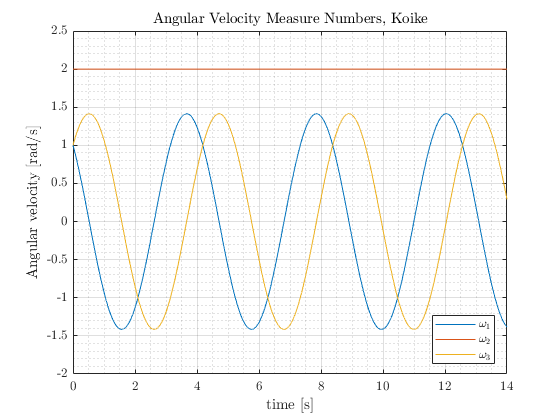

% Defining System Properties
T       = 0;                            % Torque [N m]
I_cm    = [400   0   0; 
             0 100   0;
             0   0 400];                % Inertia Dyadic [kg m2]
I       = 400;
J       = 100;

% Given Initial Conditions
w0      = [1 2 1];                      % Initial AngVel [rad s-1]
e0      = [0 0 0 1];                    % Initial Euler Parameters
C0      = [1 0 0 0 1 0 0 0 1];          % Initial DCM

% Numerically integrating dynamic and kinematic EOMs
tspan = [0 14]; % Integration time
y0 = [w0 e0 0 C0]; % Initial conditions
opt = odeset('RelTol', 1e-13, 'AbsTol', 1e-13); % Integration Tolerance
[t1, res1] = ode45(@(t,y) EOM(t,y,I,J,T), tspan, y0, opt);

% Plotting three angular velocity measure numbers over time
fig1 = figure("Renderer","painters");
    plot(t1, res1(:,1:3))
    ylabel('Angular velocity [rad/s]')
    xlabel('time [s]')
    title({'Angular Velocity Measure Numbers, Koike'})
    axis([tspan -2 2.5])
    legend('$\omega_1$', '$\omega_2$', '$\omega_3$','Location',"best")
    grid on; grid minor; box on;
saveas(fig1, fullfile(fdir, 'angVel_measure_nums.png'));

### (a)

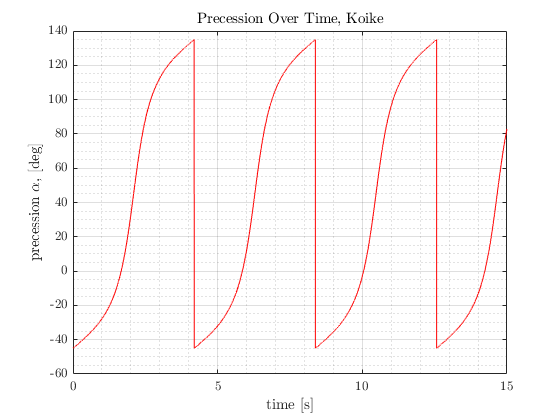

% Plotting precession and nutation angles
tspan_a = 0:0.001:15;
[t_a, res_a] = ode45(@(t,y) EOM(t,y,I,J,T), tspan_a, y0, opt); 
% Assigning computed C12, C22, and C32 to a variable 
C_a = res_a(:,9:end);
[alpha_a, gamma_a] = ang_calc_body212(C_a);

fig2 = figure(2);
    plot(t_a, alpha_a, 'r')
    xlabel('time [s]')
    ylabel('precession $\alpha$, [deg]')
    title('Precession Over Time, Koike')
    grid on; grid minor; box on;
saveas(fig2, fullfile(fdir,'alpha.png'));

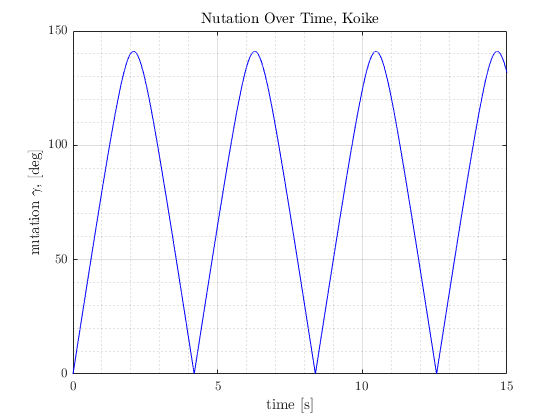


fig3 = figure(3);
    plot(t_a, gamma_a, 'b')
    xlabel('time [s]')
    ylabel('nutation $\gamma$, [deg]')
    title('Nutation Over Time, Koike')
    grid on; grid minor; box on
saveas(fig3, fullfile(fdir,'gamma.png'));

### (c)

% Integration with smaller time step
tspan_c = 0:0.05:15;
[t_c, res_c] = ode45(@(t,y) EOM(t,y,I,J,T), tspan_c, y0, opt); 
% C_new = res_c(:,9:17);

% Assigning computed C12, C22, and C32 to a variable
C11s_c = res_c(:,9);
C12s_c = res_c(:,10);
C13s_c = res_c(:,11);
C21s_c = res_c(:,12);
C22s_c = res_c(:,13);
C23s_c = res_c(:,14);
C31s_c = res_c(:,15);
C32s_c = res_c(:,16);
C33s_c = res_c(:,17);

% Finding the index when t=0.2 and t=1.5 and corresponding C12 C22 C32
index_t0p25 = find(t_c==0.25);
C11_t025 = C11s_c(index_t0p25);
C12_t025 = C12s_c(index_t0p25);
C13_t025 = C13s_c(index_t0p25);
C21_t025 = C21s_c(index_t0p25);
C22_t025 = C22s_c(index_t0p25);
C23_t025 = C23s_c(index_t0p25);
C31_t025 = C31s_c(index_t0p25);
C32_t025 = C32s_c(index_t0p25);
C33_t025 = C33s_c(index_t0p25);
C_025 = [C11_t025 C12_t025 C13_t025;
         C21_t025 C22_t025 C23_t025;
         C31_t025 C32_t025 C33_t025]

C_025 =     0.8386   -0.2287    0.4945
    0.3254    0.9382   -0.1178
   -0.4370    0.2596    0.8612



% Computing gamma
gamma = acosd(C22_t025)

gamma = 20.2438

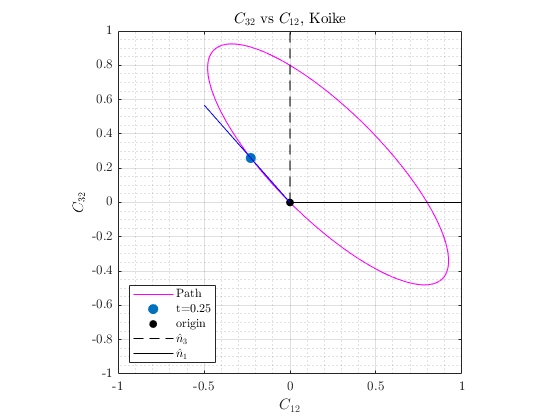


% Plotting at t = 0.2 and 1.5
fig4 = figure(4);
    plot(C12s_c, C32s_c,'-m','MarkerSize',15)
    title('$C_{32}$ vs $C_{12}$, Koike')
    xlabel('$C_{12}$')
    ylabel('$C_{32}$')
    hold on 
    plot(C12_t025, C32_t025, '.','MarkerSize',26)
    plot(0,0,'.k','MarkerSize',20)
    plot([0 0],[0 1],'--k')
    plot([0 1],[0 0],'-k')
    d = linspace(0,-0.5,100);
    plot(d,d.*(C32_t025/C12_t025),'-b')
    hold off
    legend('Path','t=0.25','origin','$\hat{n}_3$','$\hat{n}_1$',"location",'southwest')
    grid on; grid minor; axis equal; box on; 
    xlim([-1 1]); ylim([-1 1]);
saveas(fig4, fullfile(fdir, 'C12_vs_C32.png'));

### FUNCTION 

function [alphas, gammas] = ang_calc_body212(DCM)
    %{ 
       This function calculates the precession, nutation, and spin angle
       from the provided DCM 
     %}
    
    % DCM is 1 by 9 matrix with each column being C_ij
    C12s = DCM(:,2);
    C21s = DCM(:,4);
    C22s = DCM(:,5);
    C23s = DCM(:,6);
    C32s = DCM(:,8);
    
    % Preallocating alpha and gamma arrays 
    alphas = zeros([length(C12s),1]);
    gammas = zeros([length(C12s),1]);
    
    % For loop to construct alpha and gamma arrays interatively 
    for i = 1:length(alphas)
        % calculating gamma
        gammas(i) = acos(C22s(i));

        % calculating and verfying alpha
        alpha1 = round([acos(C32s(i)/sin(gammas(i))), ... 
                        -acos(C32s(i)/sin(gammas(i))), ... 
                        -acos(C32s(i)/sin(gammas(i)))+2*pi],4);
        alpha2 = round([asin(C12s(i)/sin(gammas(i))), ... 
                        pi-asin(C12s(i)/sin(gammas(i))), ...
                        pi-asin(C12s(i)/sin(gammas(i)))],4);
        if i == 1
            alphas(i) = deg2rad(-44.9829164957209);
        else  
            alphas(i) = intersect(alpha1, alpha2); 
        end
        gammas(i) = rad2deg(gammas(i));
        alphas(i) = rad2deg(alphas(i));
    end
end